# Removing Noise from a Binary Mask

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

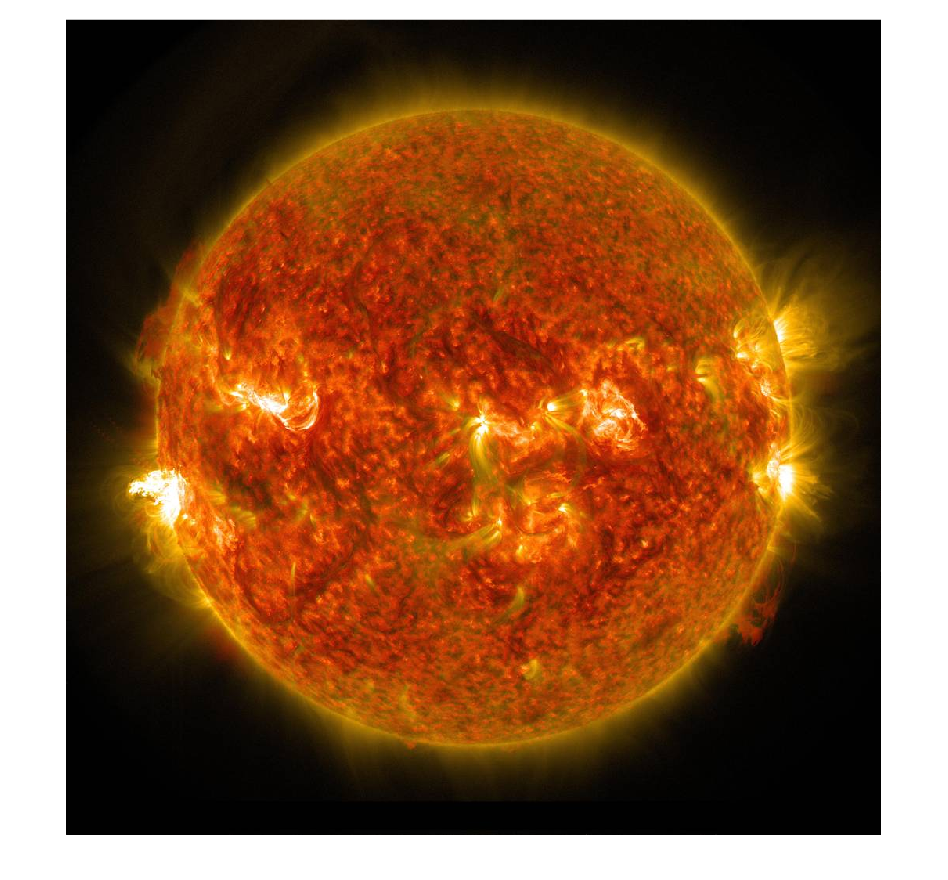

sf = imread("./images/solarFlare.jpg");
imshow(sf)

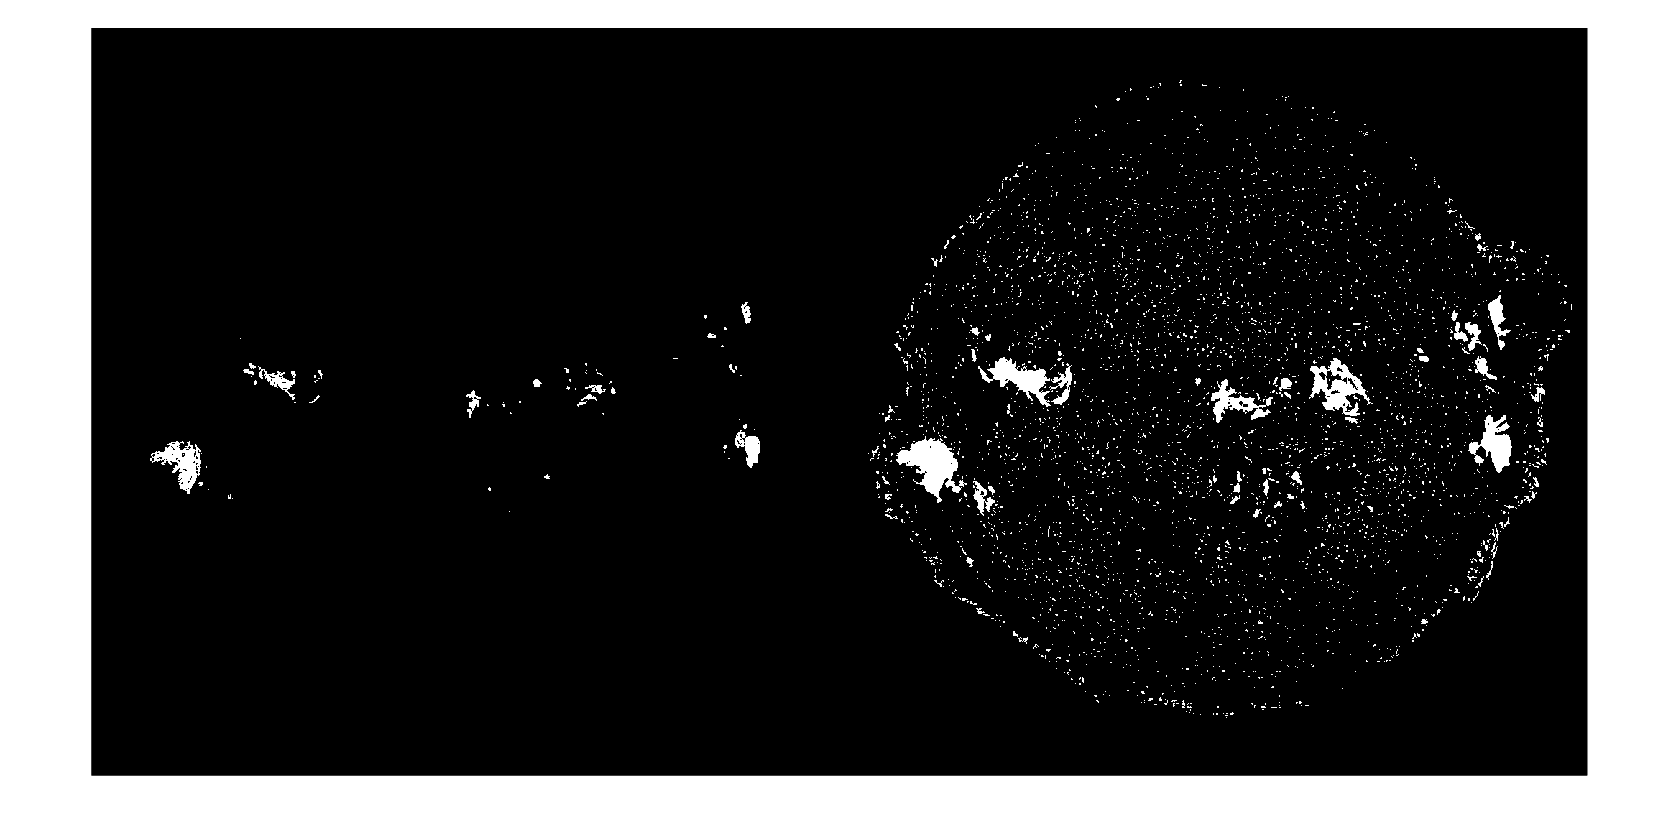


sfHSV = rgb2hsv(sf);
[h,s,v] = imsplit(sfHSV);
sfBWlessCoverage = s < .5 & v > .95;
sfBW = s < 0.9 & v > 0.25;
imshowpair(sfBWlessCoverage, sfBW, "montage")

## Task 1

Using a strict threshold creates a segmentation that misses some of the solar flares. By loosening the threshold, you can include more of the solar flares. The new threshold will also include more noise, but you can deal with that in post-processing.

To fill in holes in a segmentation, you can use the `imfill` function.

`BW2` `=` `imfill``(``BW``,``"holes"``)``;`

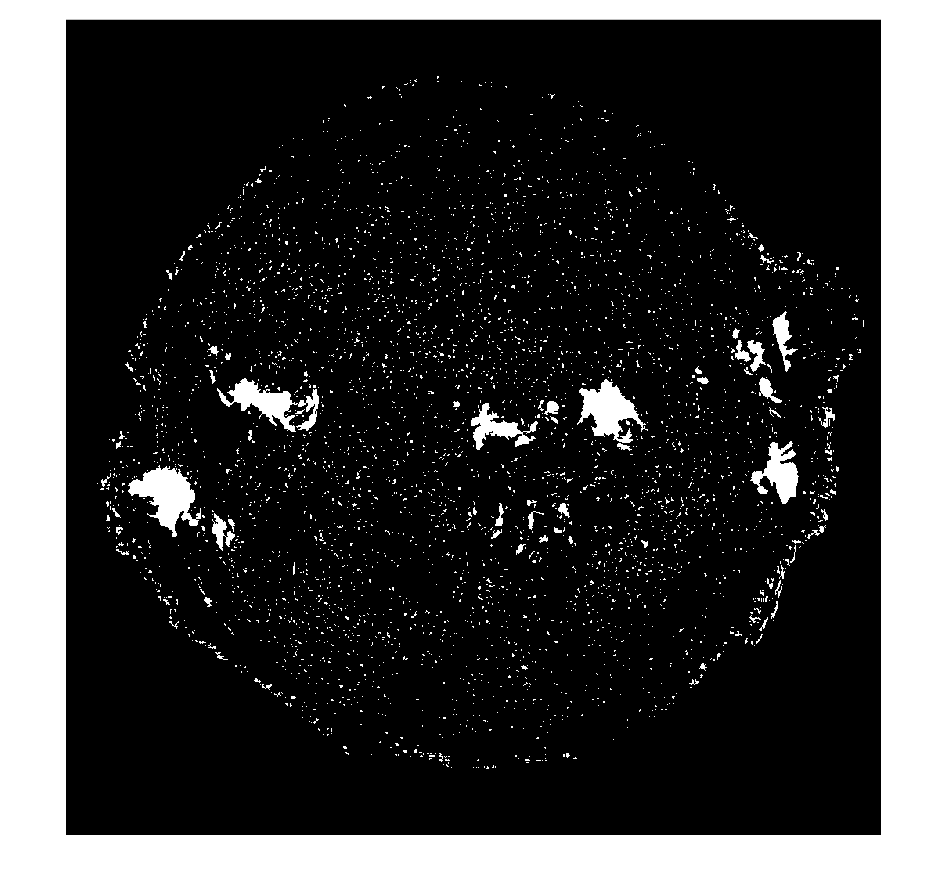

sfBWfill = imfill(sfBW,"holes");
imshow(sfBWfill)

## Task 2

The holes in the segmentation are filled, but there is still a lot of static noise. You can remove small areas of foreground (white regions) with `bwareaopen`.

`BW2` `=` `bwareaopen``(``BW``,``n``)``;`

All areas of foreground made up of fewer than `n` pixels are removed.

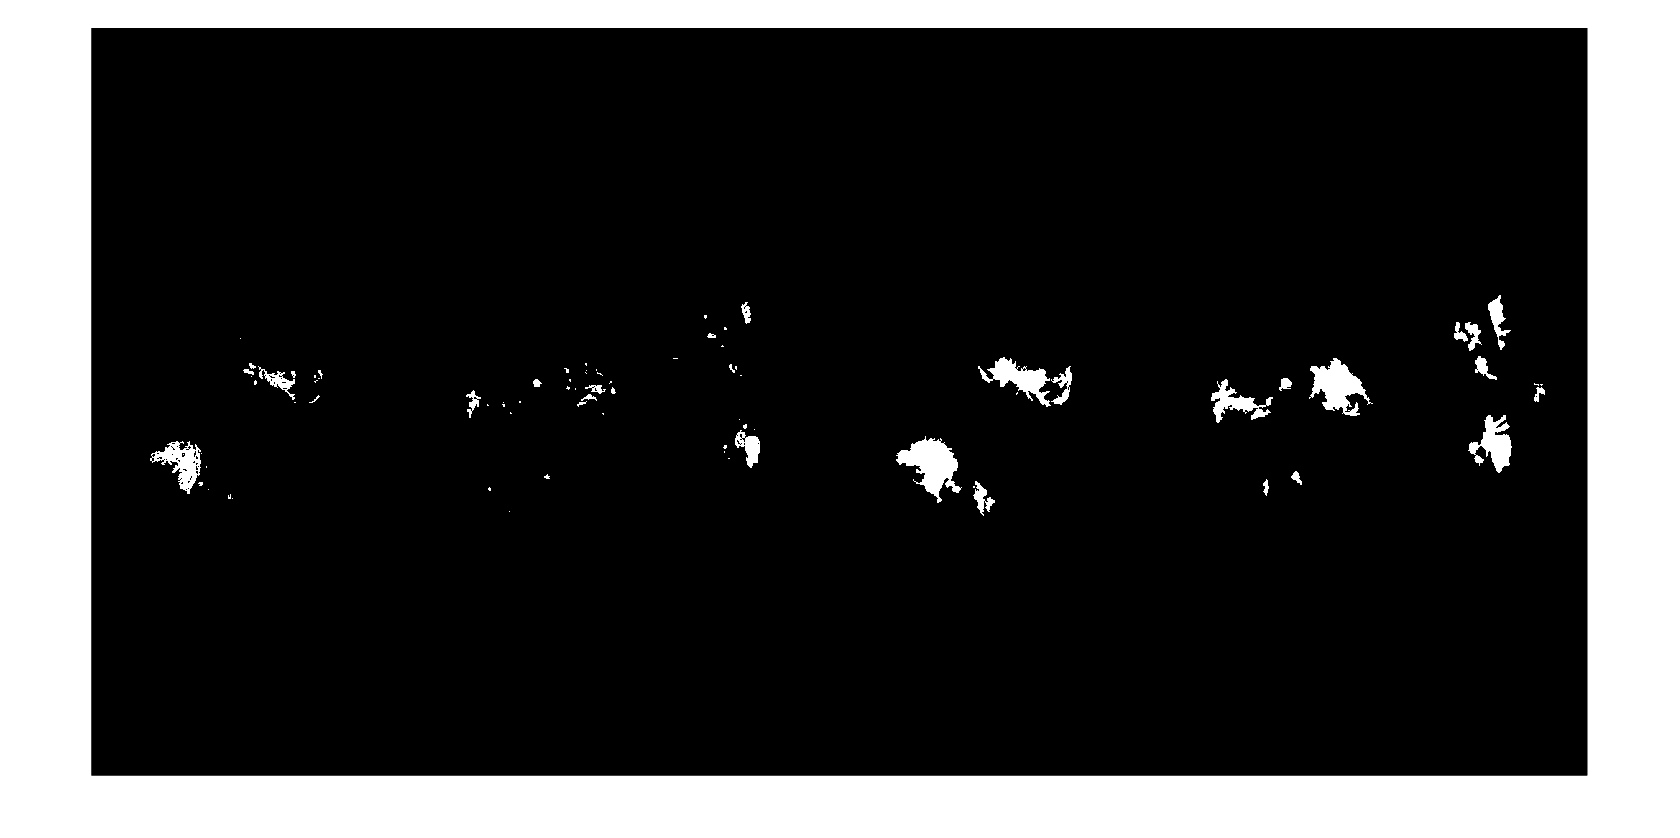

BWclean = bwareaopen(sfBWfill, 100);
imshowpair(sfBWlessCoverage, BWclean, "montage")